# Analysis of Relative Fixation Duration

## Housekeeping

% clear the workspace
clear;close all; clc

### Variable Definitions

The mat file below contains two tables, called *fixDat *& *secondFix, *which contain the data necessary to generate figures 2c and 2d in the main text, respectively.

Both tables contain the following variables:

- fixationDuration: fixation duration in seconds

- fixationType: categorical variable indicating if a fixation is first, middle, or last

- monkey: monkey indicator

The *fixDat* table also includes a variable named *session* which groups the data according to session. 

### Load the data

% load in the data
load RelativeFixationDuration.mat

## Relative Fixation Duration 

The following code generates the bar graph from Figure 2c of the main text 

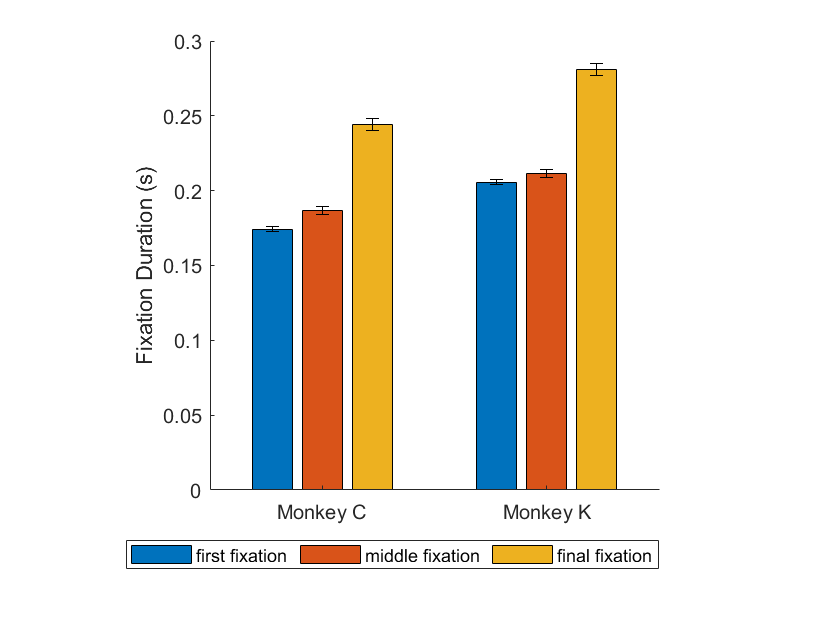

% open figure
figure(1)

% calculate session-wise statistics 
fixs = grpstats(fixDat,{'session','fixationType','monkey'},{'mean'},...
    'DataVars','fixationDuration');
fixs2 = grpstats(fixs,{'fixationType','monkey'},{'mean','sem'},...
    'DataVars',{'mean_fixationDuration'});

% combine means and sems together
jointFix = [fixs2(fixs2.monkey == "Monkey C",:).mean_mean_fixationDuration'; fixs2(fixs2.monkey == "Monkey K",:).mean_mean_fixationDuration'];
jointFix2 = [fixs2(fixs2.monkey == "Monkey C",:).sem_mean_fixationDuration'; fixs2(fixs2.monkey == "Monkey K",:).sem_mean_fixationDuration'];

% plot graph using session-wise SEM for error bars
fd = bar(jointFix); hold on
errorbar([fd.XEndPoints],[fd.YEndPoints],reshape(jointFix2, [1 6]),...
    'LineStyle',"none","Marker",'none', "Color",'k')
xticklabels({'Monkey C','Monkey K'})
ylabel('Fixation Duration (s)')
pbaspect ([1 1 1])
box off   
legend('first fixation','middle fixation', 'final fixation',"numColumns",3,"location", 'southoutside')

## Second Fixations: Terminal Non-Decision Time (NDT)

The following code generates the violin plot shown in Figure 2d of the main text. Note that, for this figure and the NDT calculations, the data come from second fixations on trials where the two targets were of equal value. (see text for rationale). 

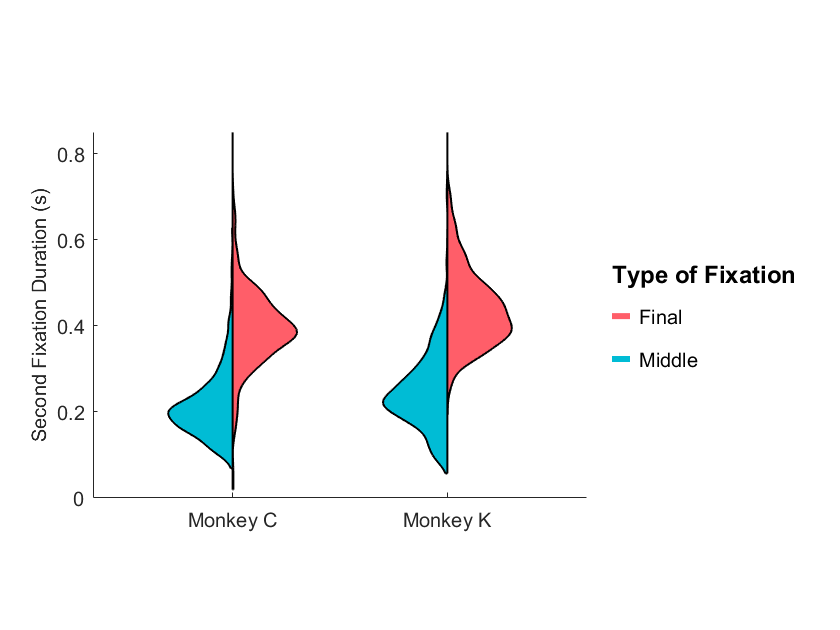

figure(2)
g = gramm('x',secondFix.monkey,'y',secondFix.fixationDuration,'color',secondFix.fixationType);
g.stat_violin('half',1,'normalization','width');
g.axe_property('DataAspectRatio',[2 1 1],'Ylim',[0 0.85]);
g.set_names("x",'','color','Type of Fixation','y','Second Fixation Duration (s)');
g.draw();